# Supply Chain Network Simulator

Designing the Supply Chain Network

clear all
close all
clc

rng(7)

caseNum = 2;

if caseNum == 1
    numOfChains = 2;            % Number of parallel chains
    numOfInventories = 3;       % Number of inventories in each chain
    matFile = 'Results/Case1/gridSearchCompleteDesignResults.mat';
elseif caseNum == 2
    numOfChains = 3;            % Number of parallel chains
    numOfInventories = 4;       % Number of inventories in each chain
    matFile = 'Results/Case2/gridSearchCompleteDesignResults.mat';
elseif caseNum == 3
    numOfChains = 4;            % Number of parallel chains
    numOfInventories = 5;       % Number of inventories in each chain
    matFile = 'Results/Case3/gridSearchCompleteDesignResults.mat';
end

% Create Network
netId = 1;               % Supply chain network ID
net = Network(netId, numOfChains, numOfInventories);

Started creating the supply chain network.
Started creating chain 1
Finished creating a chain...
Started creating chain 2
Finished creating a chain...
Started creating chain 3
Finished creating a chain...
Finished creating the supply chain network.


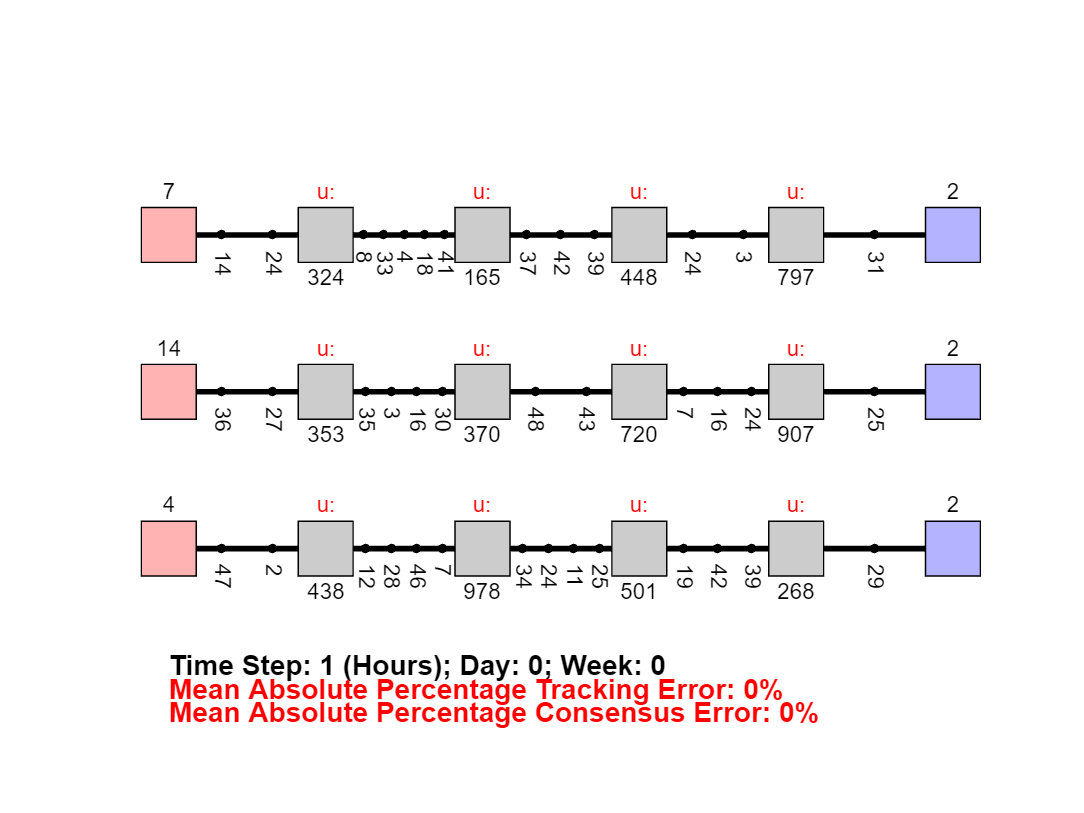


% SCN setup and the initial condition
figNum = 1;
figure(figNum);
hold on; axis equal; axis off;
net.draw(1);


tMax = 500;
saveMode = 3; % 1 FigSave, 2 vidSave, 3 display

save(['tempNet',num2str(caseNum)])
save('caseNum','caseNum')

K = 0, L = 0

clear all
close all
clc

load('caseNum.mat')
tagVal = 'Steady';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    net.chains{i}.LLocal = 0*net.chains{i}.LLocal;
end
net.chains{1}.LLocal

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


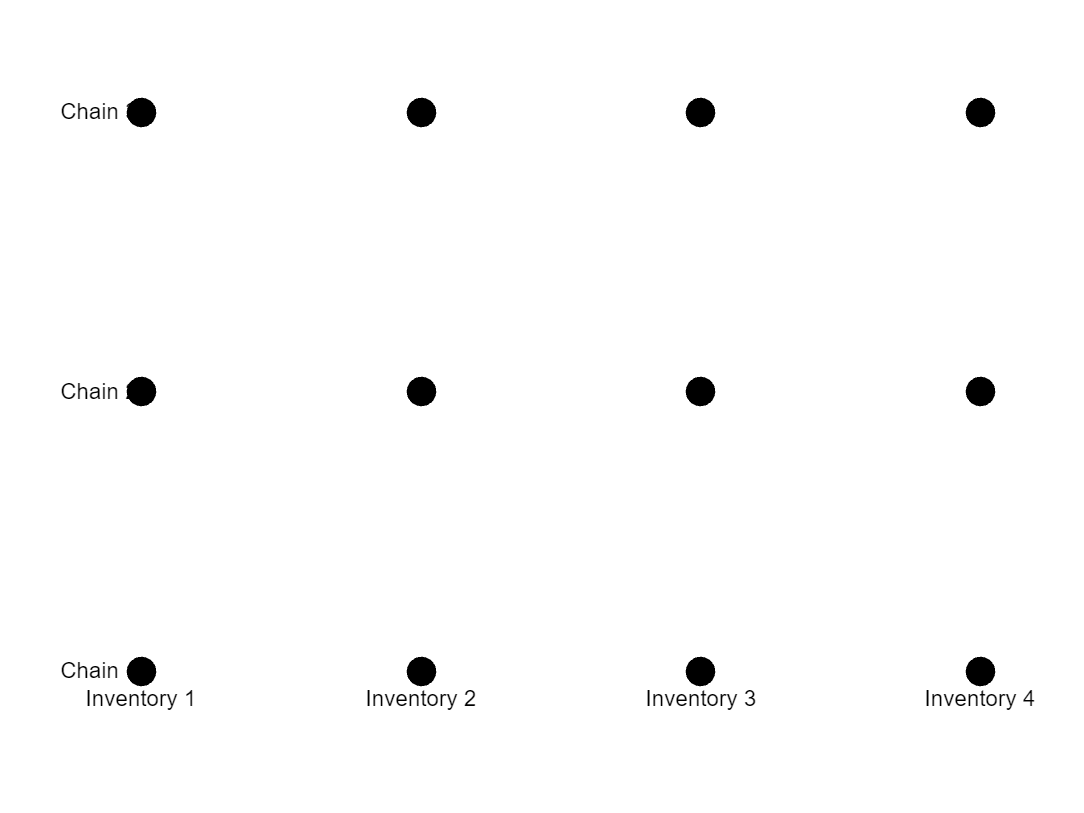

net.KGlobal = 0*net.KGlobal;
net.setAdjointMatrixAndNeighborsAndControllers();


% Communication topology of the arbitrarily global controllers
figNum = figNum + 1;
figure(figNum); 
hold on; axis equal; axis off;
net.plotConnections(net.adjMat);

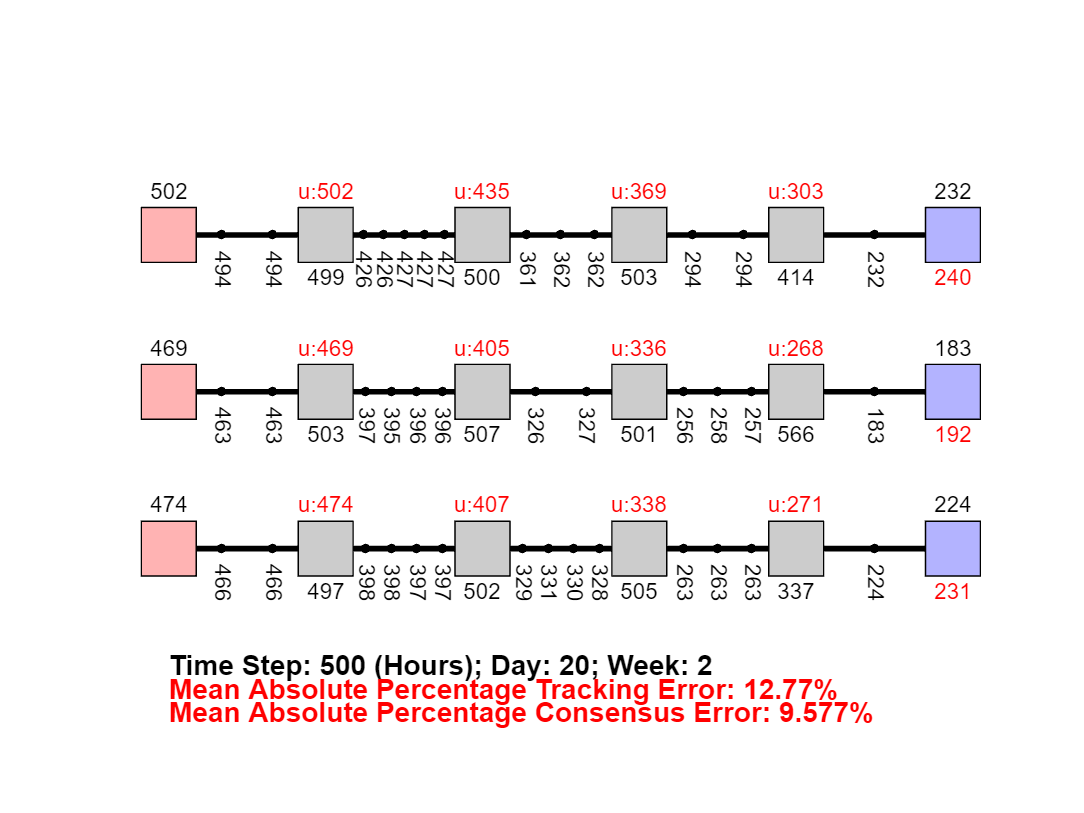

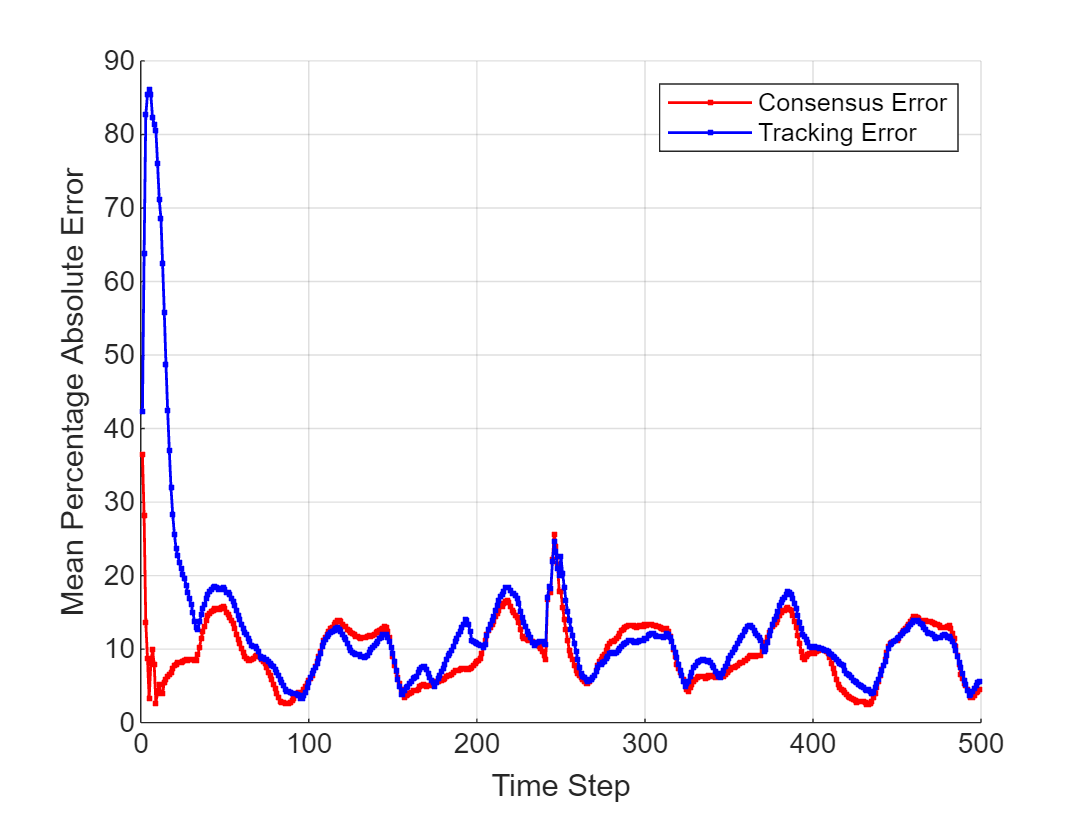

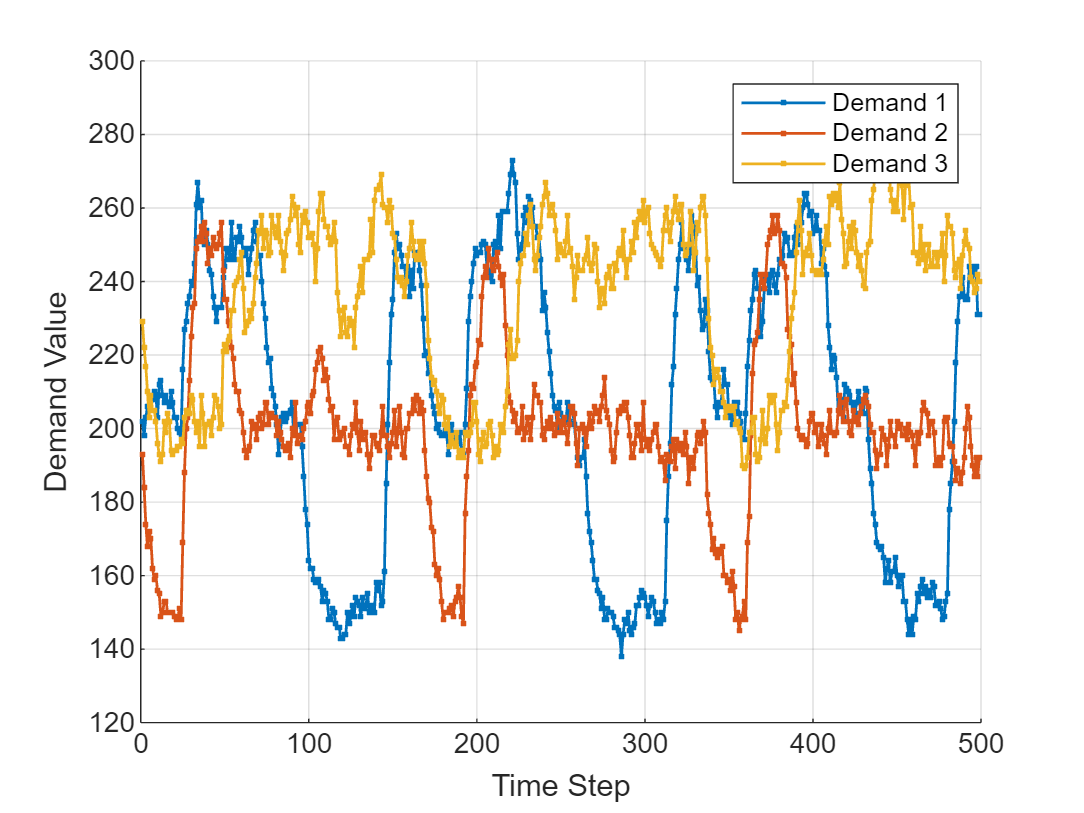


% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:(tMax-1)
        net.update();  % Update the entire network
    end
    
    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);
    
    % % Performance plot
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();

    % % Performance plot
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on;
    net.plotDemandProfiles();
end

K = 0

clear all
close all
clc

load('caseNum.mat')
tagVal = 'NullGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    pVal = 1/numOfChains;
    deltaCostCoef = -1000;
    net.chains{i}.localControlDesign(pVal,deltaCostCoef);
end
net.chains{1}.LLocal

ans =    -0.6643   -0.9339   -0.8932   -0.7115   -0.7387   -0.7565   -1.0378   -1.1002   -1.1213   -1.0854   -0.9928   -1.0807   -1.1549   -1.2113   -0.7905   -0.8782   -0.9700
   -0.0487   -0.6265   -0.5985   -0.4758   -0.0533   -0.1341   -0.6966   -0.7402   -0.7666   -0.7791   -0.6649   -0.7231   -0.7763   -0.8215   -0.5287   -0.5876   -0.6468
   -0.1576   -0.1174   -0.4595   -0.3670   -0.1756   -0.1598   -0.1296   -0.2558   -0.3109   -0.3210   -0.5105   -0.5605   -0.5992   -0.6321   -0.4078   -0.4530   -0.5054
   -0.0659   -0.1342    0.0530   -0.3259   -0.0737   -0.0665   -0.1488   -0.1584   -0.1495   -0.1446    0.0595   -0.0853   -0.1603   -0.1865   -0.3621   -0.4025   -0.4330


net.KGlobal = 0*net.KGlobal;
net.setAdjointMatrixAndNeighborsAndControllers();


% Communication topology of the arbitrarily global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMat);

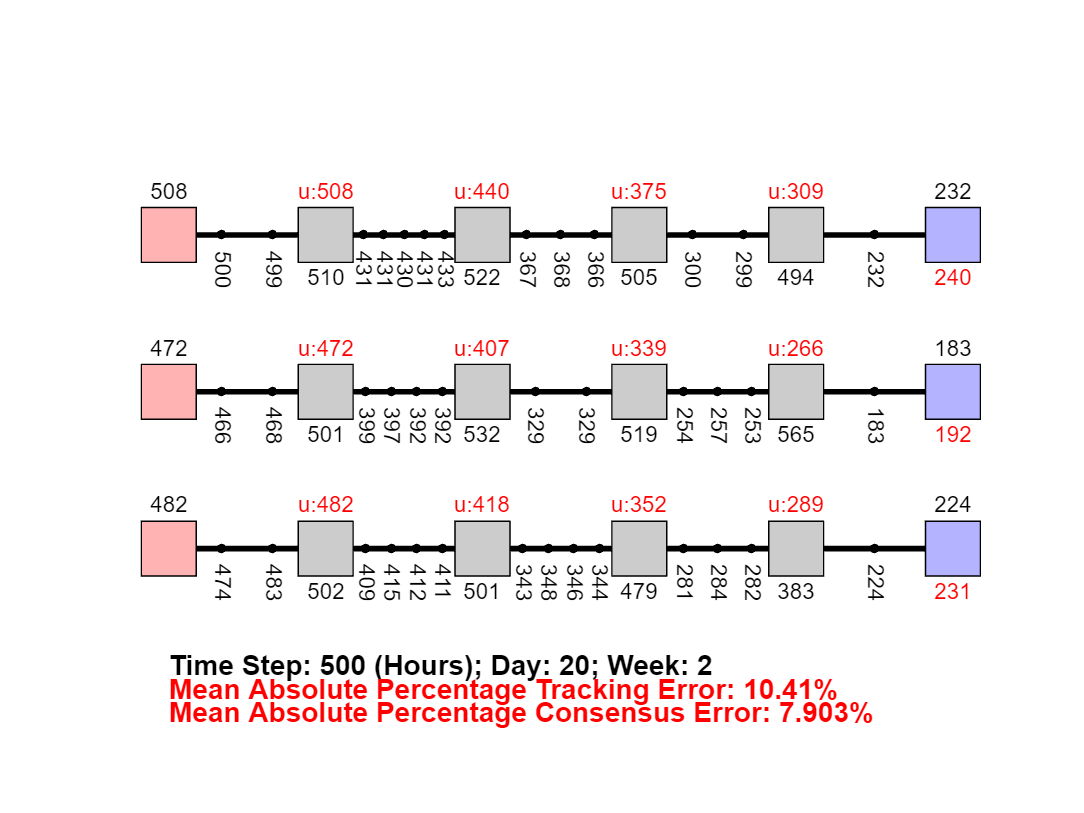

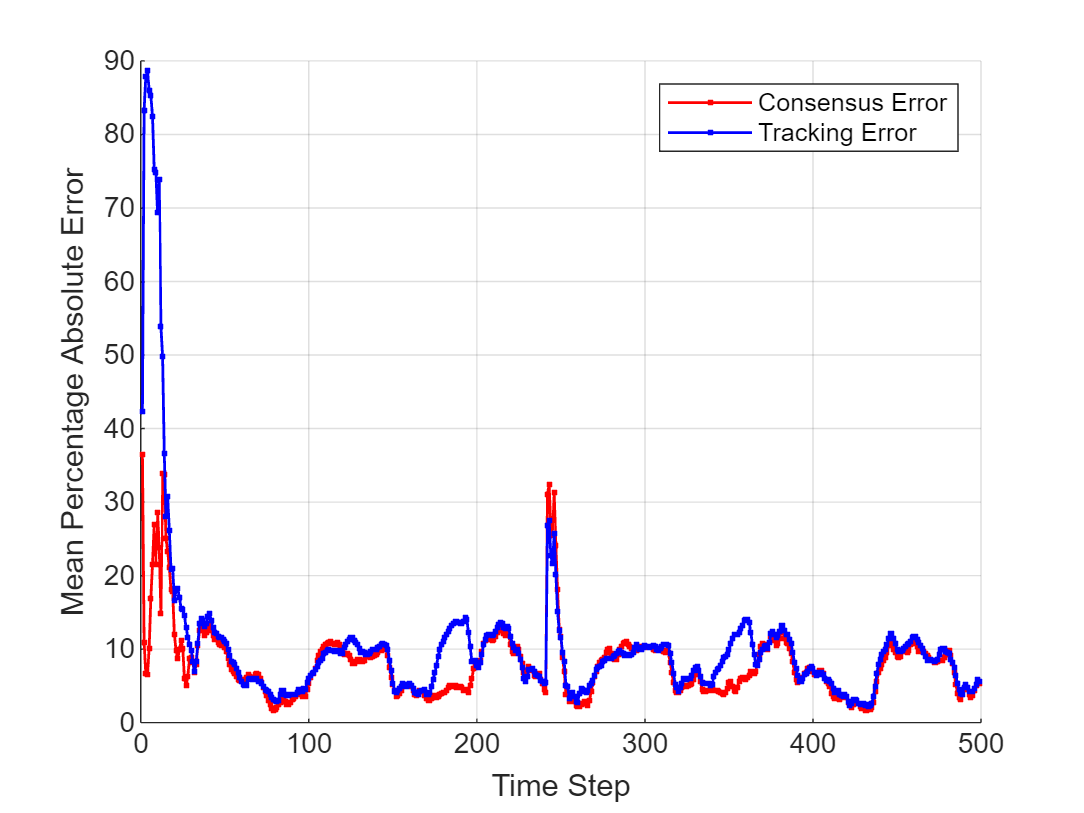


% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:(tMax-1)
        net.update();  % Update the entire network
    end
    
    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);
    
    % % Performance plot
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
end

Hard Graph

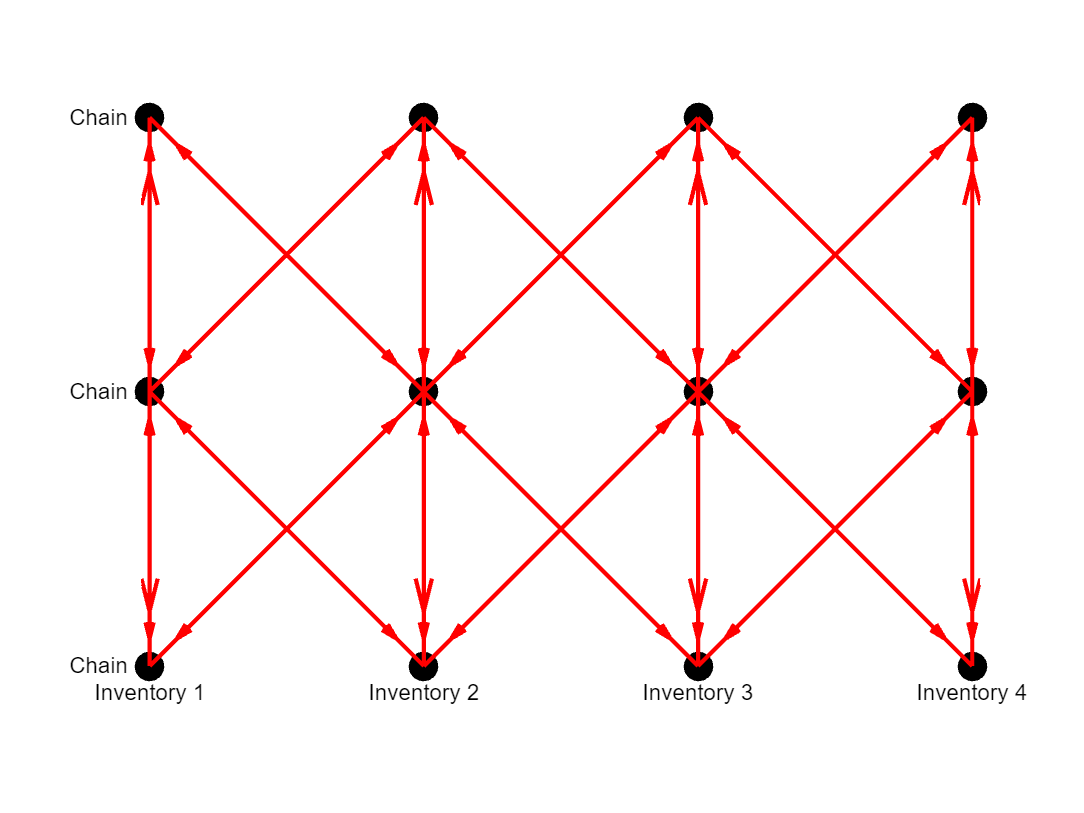

clear all
close all
clc

load('caseNum.mat')
tagVal = 'HardGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Desired communication topology
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMatRef);


% Some arbitrarily designed local and global controllers:
net.chains{1}.LLocal

ans =    -0.6648   -0.9342   -0.8931   -0.7114   -0.7393   -0.7566   -1.0380   -1.1001   -1.1209   -1.0862   -0.9927   -1.0806   -1.1548   -1.2108   -0.7905   -0.8782   -0.9702
   -0.0470   -0.6260   -0.5986   -0.4759   -0.0512   -0.1328   -0.6963   -0.7404   -0.7675   -0.7786   -0.6650   -0.7234   -0.7766   -0.8221   -0.5288   -0.5877   -0.6470
   -0.1594   -0.1178   -0.4595   -0.3669   -0.1778   -0.1614   -0.1298   -0.2559   -0.3098   -0.3209   -0.5107   -0.5601   -0.5991   -0.6319   -0.4076   -0.4530   -0.5048
   -0.0664   -0.1345    0.0530   -0.3258   -0.0744   -0.0671   -0.1492   -0.1582   -0.1496   -0.1447    0.0599   -0.0857   -0.1598   -0.1860   -0.3620   -0.4023   -0.4333


net.KGlobal

ans =     0.0000    0.0008    0.0003         0    0.0009    0.0005         0         0    0.0002         0         0         0
    0.0013    0.0003    0.0007   -0.0000    0.0005    0.0008    0.0005         0         0    0.0003         0         0
    0.0003    0.0013    0.0003    0.0002         0    0.0005    0.0008    0.0008         0         0    0.0003         0
         0    0.0003    0.0013    0.0004         0         0    0.0005    0.0009         0         0         0    0.0003
    0.0004    0.0003         0         0    0.0004    0.0005    0.0002         0    0.0004    0.0003         0         0
    0.0003    0.0005    0.0003         0    0.0006    0.0004    0.0005    0.0000    0.0003    0.0005    0.0003         0
         0    0.0003    0.0005    0.0003    0.0002    0.0006    0.0004    0.0005         0    0.0003    0.0005    0.0003
         0         0    0.0003    0.0005         0    0.0002    0.0006    0.0007         0         0    0.0003    0.0005
    0.0002         0      


% Communication topology of the arbitrarily global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMat);

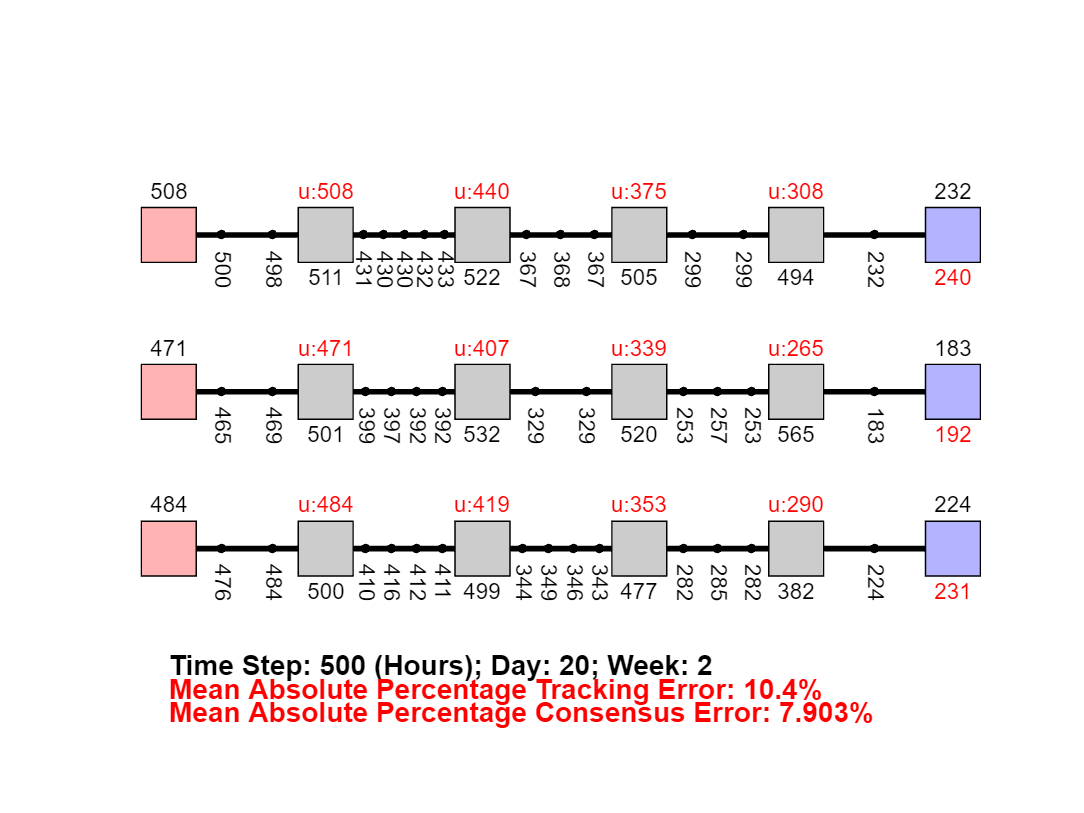

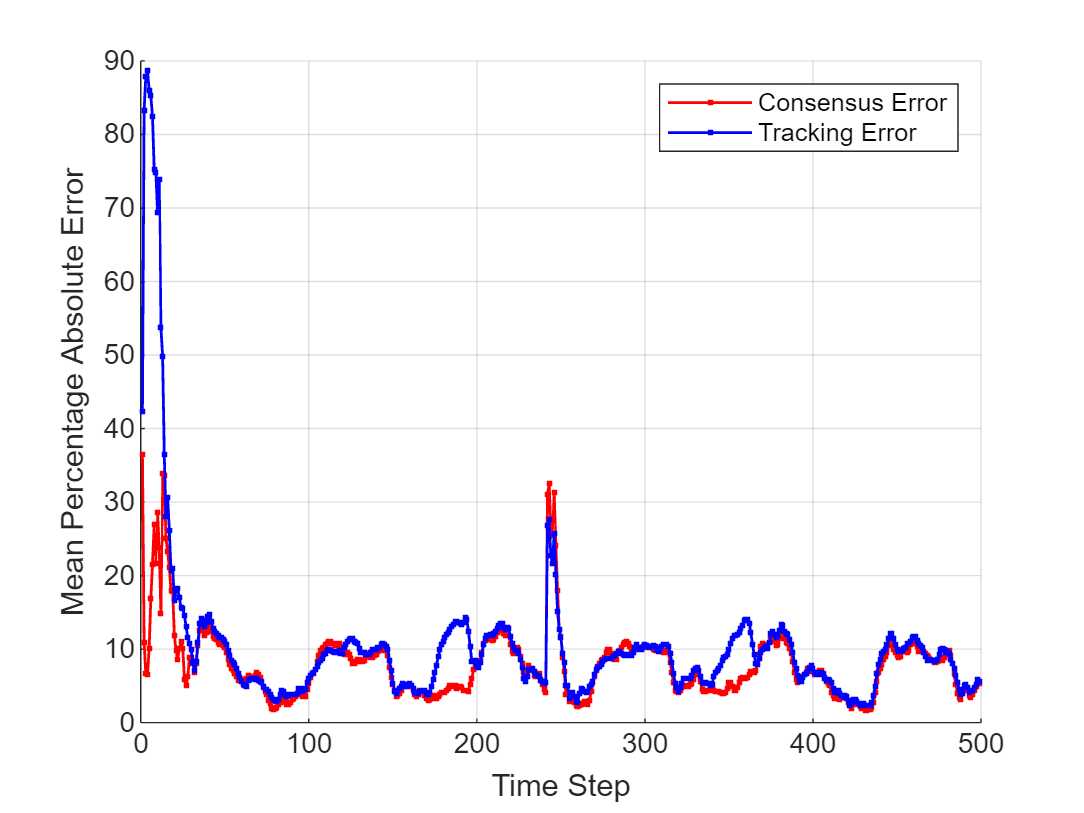


% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:(tMax-1)
        net.update();  % Update the entire network
    end
    
    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);
    
    % % Performance plot
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
end

Soft Graph

clear all
close all
clc

load('caseNum.mat')
tagVal = 'SoftGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])
rng(7)

isSoft = 1;

% Grid Search Functions (Execute this seperately as it takes time)
% search input parameters: pVal, deltaCostCoef, gammaCostCoef, comCostLimit
% search output metrics: LNorm, KNorm, GammaTilde, KLinks
% net.gridSearchCompleteDesign(folderName)

% Selecting best parameters that optimize the objective J:
% J = d1 * LNormVal + d2 * KNormVal + d3 * gammaTildeVal + d4 * NumOfLinks
d1 = 0;
d2 = -0;
d3 = 2;
d4 = 1;
[pVal, deltaCostCoef, gammaCostCoef, comCostLimit, KLinks] = net.findBestParameters(matFile,d1,d2,d3,d4) 

Best parameter combination found:
Minimum objective value: 0.0013645
pVal: 0.01
deltaCostCoef: 1
gammaCostCoef: 1
comCostLimit: 0.01
LNorm: 4.745
KNorm: 0.097415
gammaTilde: 116.608
KLinks: 82


pVal = 0.0100

deltaCostCoef = 1

gammaCostCoef = 1

comCostLimit = 0.0100

KLinks = 82


%% Applying the found best parameters to design the local and global controllers
% Local controller design
totalStatusLocal = 1;
totalLNorm = 0;
for i = 1:1:net.numOfChains
    [statusLocal, ~, ~, LNormVal, ~, ~] = net.chains{i}.localControlDesign(pVal, deltaCostCoef);
    if ~statusLocal
        totalStatusLocal = 0;
        break;
    else
        totalLNorm = totalLNorm + LNormVal;
    end
end
totalStatusLocal

totalStatusLocal = 1

totalLNorm = totalLNorm / net.numOfChains

totalLNorm = 4.7450

% Global controller design
if totalStatusLocal
    [statusGlobal, gammaTildeVal, ~, ~, KNormVal] = net.globalControlDesign(gammaCostCoef,comCostLimit,isSoft)
end

statusGlobal = logical
   1


gammaTildeVal = 116.6080

KNormVal = 0.0974

net.setAdjointMatrixAndNeighborsAndControllers(); % Load Graph, neighbors and controllers from KVal

% Optimizally designed local and global controllers:
net.chains{1}.LLocal

ans =    -0.6628   -0.9403   -0.8993   -0.7143   -0.7368   -0.7591   -1.0445   -1.1083   -1.1314   -1.0898   -0.9991   -1.0873   -1.1615   -1.2154   -0.7937   -0.8820   -0.9712
   -0.0564   -0.6368   -0.6075   -0.4832   -0.0627   -0.1402   -0.7076   -0.7510   -0.7743   -0.7901   -0.6750   -0.7338   -0.7876   -0.8341   -0.5369   -0.5965   -0.6575
   -0.1550   -0.1219   -0.4676   -0.3750   -0.1720   -0.1553   -0.1356   -0.2614   -0.3190   -0.3274   -0.5197   -0.5724   -0.6112   -0.6472   -0.4166   -0.4629   -0.5177
   -0.0660   -0.1335    0.0499   -0.3302   -0.0731   -0.0648   -0.1485   -0.1601   -0.1487   -0.1452    0.0554   -0.0869   -0.1663   -0.1913   -0.3669   -0.4075   -0.4399


net.KGlobal

ans =    -0.0006    0.0202    0.0281    0.0049    0.0003    0.0168    0.0315    0.0071    0.0020    0.0280    0.0339    0.0052
    0.0002         0         0         0    0.0001         0         0         0    0.0001         0         0         0
    0.0001    0.0001         0         0    0.0001         0         0         0    0.0001         0         0         0
    0.0001         0    0.0001         0    0.0001    0.0001         0         0    0.0002         0         0         0
         0    0.0004    0.0078    0.0375   -0.0219    0.0001    0.0076    0.0411    0.0074         0    0.0093    0.0446
    0.0035   -0.0001         0    0.0010    0.0055   -0.0072    0.0004    0.0025    0.0033    0.0022         0    0.0006
    0.0068         0   -0.0015    0.0009    0.0082    0.0010   -0.0072    0.0035    0.0079         0         0         0
    0.0076    0.0043    0.0003   -0.0017    0.0083    0.0062    0.0019   -0.0069    0.0089    0.0043         0   -0.0001
    0.0038    0.0070    0.

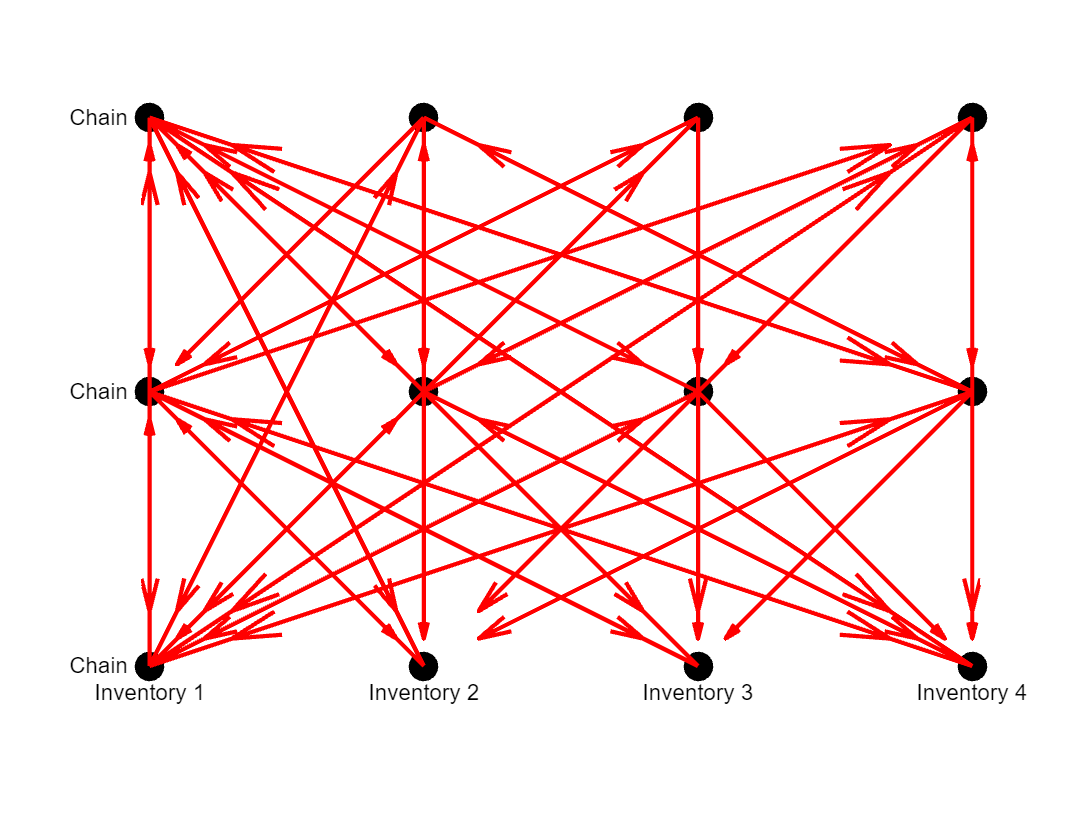


% Communication topology of the optimized global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMat);

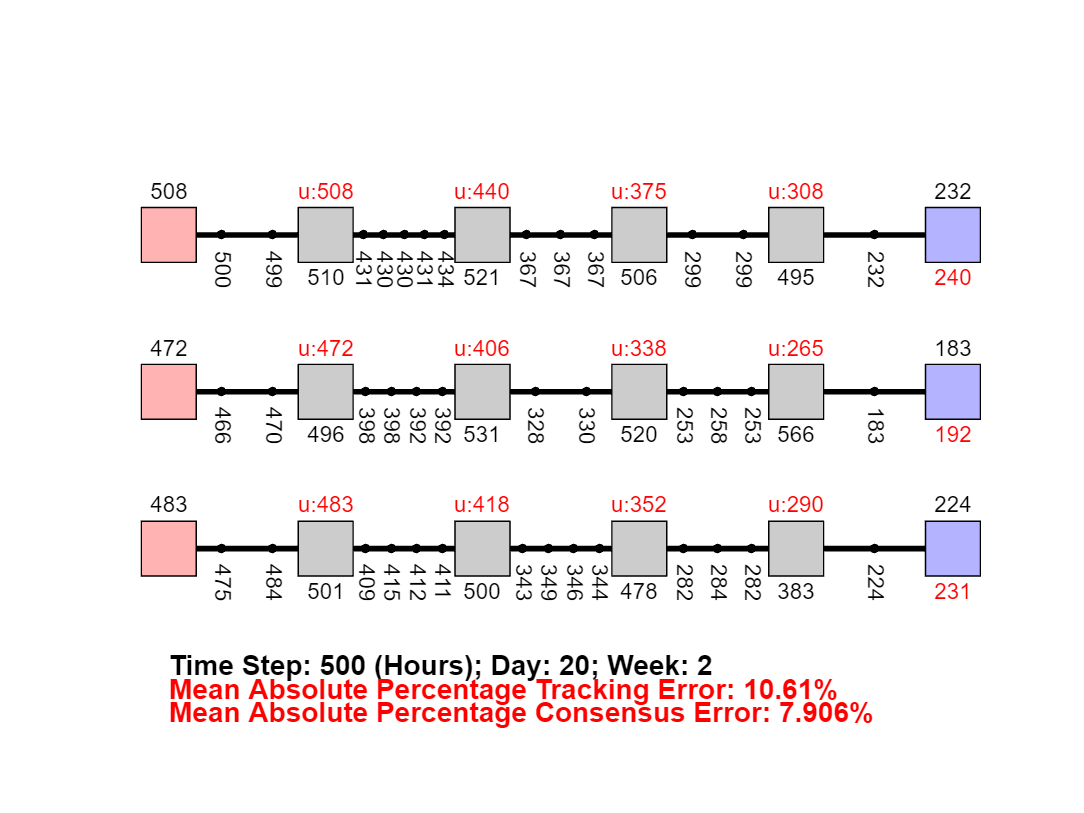

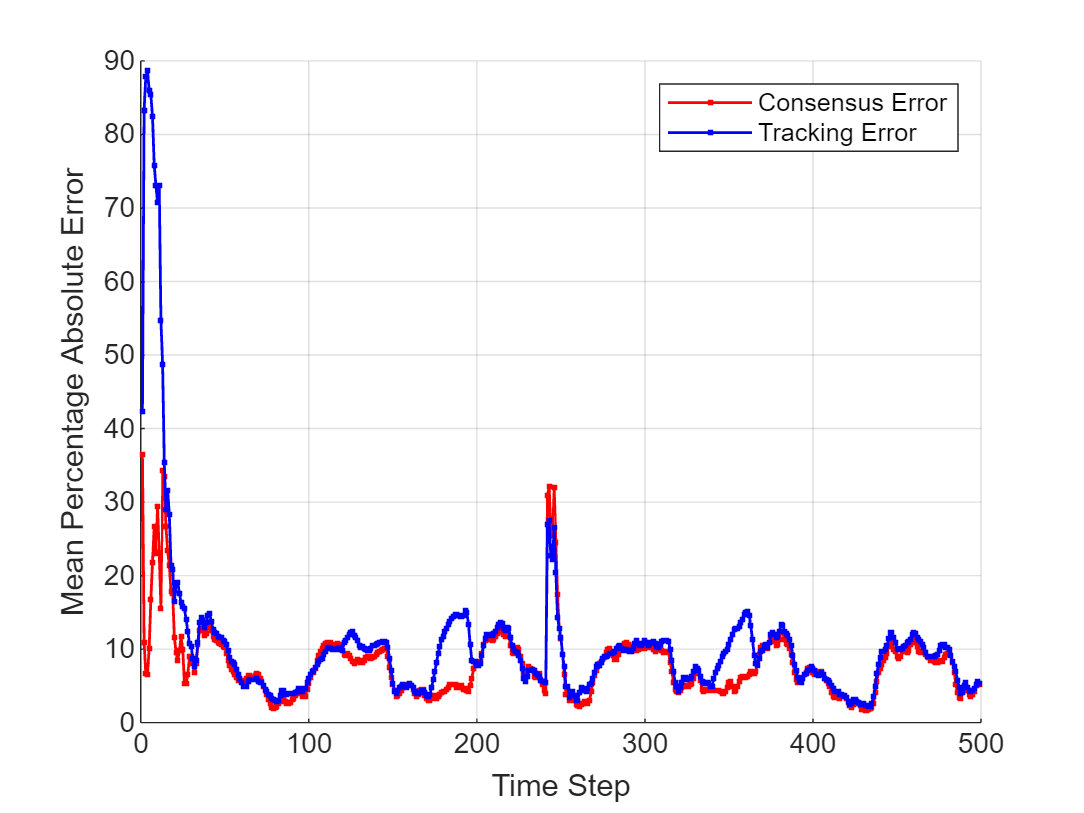


% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:(tMax-1)
        net.update();  % Update the entire network
    end
    
    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);
    
    % % Performance plot
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
end


% What are the inventory capacities that will not limit controllers?
% How to improve tracking error performance without compromizing consensus
% error performance? - Change the local controller design approach....
% Local controllers being overly strong might be causing the osillatory
% behavior, - high control inputs causing overshoots...
% Is there an additional condition on KGlobal for conesensus_tracking
% (e.g., K*1 = 0?, read consensus notes/discussion)